Generate simulated spectrograms using the following script:

## Load simulated spectrograms into a datastore

I tried using the simulations from the original python dataset. This resulted in quickly overtrained networks. I'm guessing this is because the spikes are so well aligned (see below). The alignement is because the simulations create spikes (spike/ripples) at regular 1s intervals and the trace segmenting algorithm uses sliding windows at .5 s intervals.

% Simulations from generate_simulated_spectrograms go here and don't need
% to be transformed
directory = 'contributors/emily/SimulatedSpectrograms/';
readFun = @imread;

This is what 

                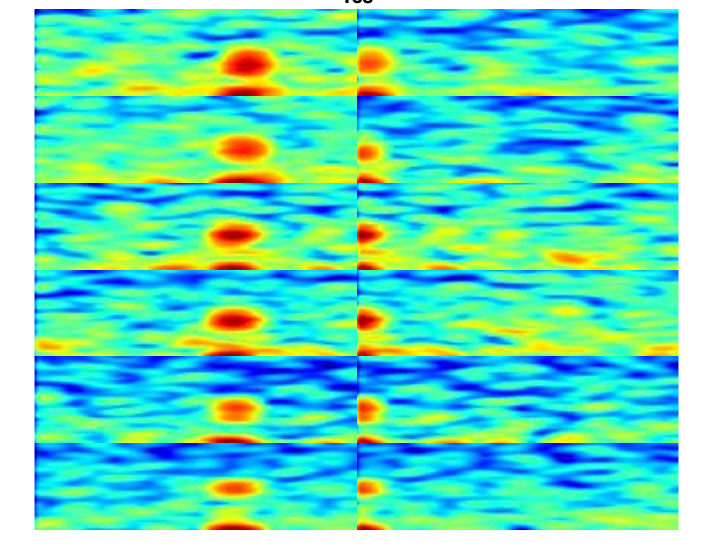

imds = imageDatastore( ...
    directory ...
    , 'IncludeSubfolders', true ...
    , 'LabelSource','foldernames' ...
    , 'ReadFcn', readFun ...
    );

imds.Labels = categorical(lower(string(imds.Labels)));

[imdsTrain, imdsVal] = splitEachLabel(imds, .9, 'randomized');


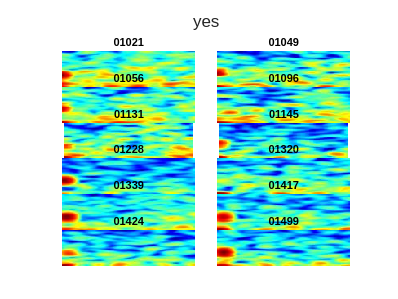

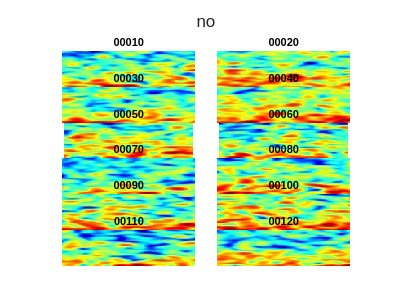


for label = ["yes", "no"]
    figure;
    T = tiledlayout(6, 2, 'TileSpacing', 'none');

    for ii = find(imdsTrain.Labels == label, 12)'
        nexttile(T)
        fname = imdsTrain.Files{ii};
        imshow(imdsTrain.readimage(ii));
        ttl = title(fname(end-8:end-4) ...
            ..., 'VerticalAlignment', 'top' ...
            );
    end
    title(T, label)
end


% 
% 
% for label = ["Yes", "No"]
%     figure
%     montage(mat2cell( ...
%         imdsTrain.subset(find(imdsTrain.Labels == label, 12)).transform(@(x) imresize(x, [224 224])).readall() ...
%         , repmat(224, 12, 1)) ...
%         );
%     title(label)
% end


% Load GoogLeNet
net = googlenet;

% Determine the size of inputs for googlenet
inputSize = net.Layers(1).InputSize;
lgraph = layerGraph(net); 

% Correct the last layers to match the output size
numClasses = numel(categories(imds.Labels));
newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...  % these are from the matlab example
    'BiasLearnRateFactor',10 ...
    );
    
lgraph = replaceLayer(lgraph,'loss3-classifier',newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);


%% train the network
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection', true ...
    );
augimdsTrain = augmentedImageDatastore( ...
    inputSize(1:2),imdsTrain ...
    , "OutputSizeMode", "resize" ...
    ..., 'DataAugmentation',imageAugmenter ...  % augment?
    );
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsVal);

minibatchSize = 8;
validationFreq = floor(numel(imdsTrain.Files)/minibatchSize);
options = trainingOptions( ...
    'sgdm' ...
    , 'MiniBatchSize',minibatchSize ...
    , 'MaxEpochs',6 ...
    , 'InitialLearnRate',1e-3 ...
    , 'Shuffle','every-epoch' ...
    , 'ValidationData',augimdsValidation ...
    , 'ValidationFrequency',validationFreq ...
    , 'Verbose',false ...
    , 'Plots','training-progress' ...
    );


if 0  % retrain?
    netTransfer = trainNetwork(augimdsTrain, lgraph, options);
else
    load('contributors/emily/googlenet_tunedOnSims.mat')
end
% this model didn't really finish training but continuing on
% just to get a taste.

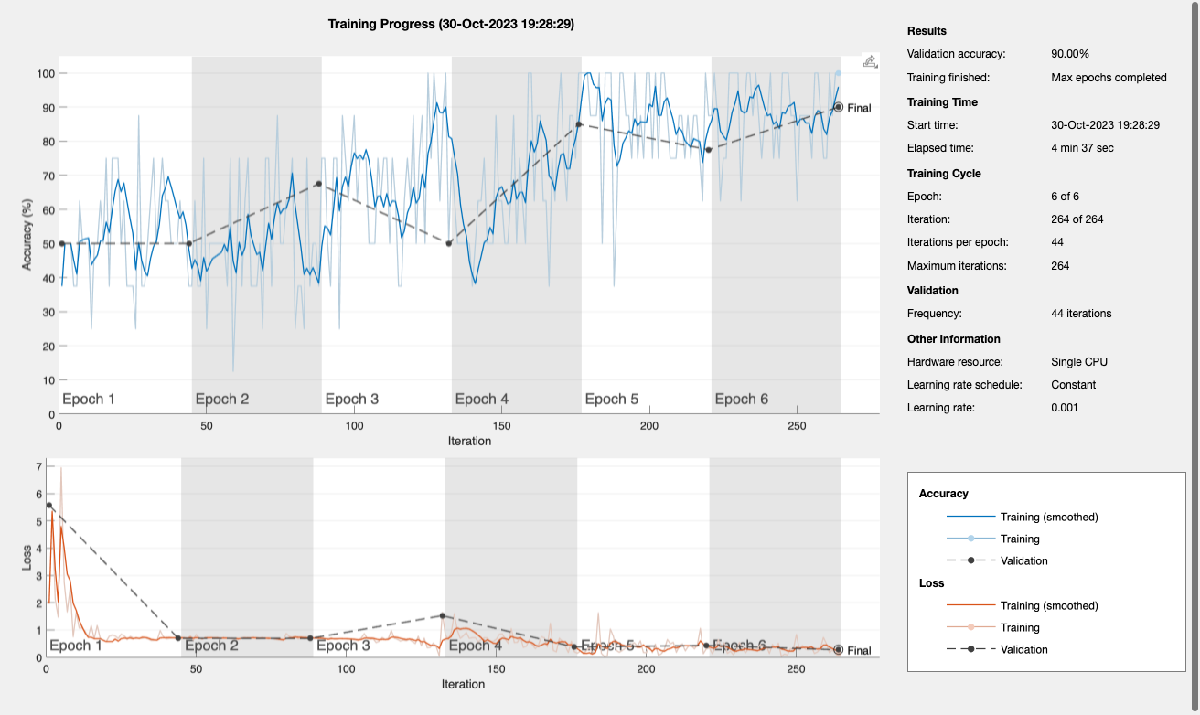

%% Classify spectrograms from real patients
imdsTest = imageDatastore('Spike_Ripple_Training_Data/spectrograms/silver/' ...
    , 'IncludeSubfolders', true ...
    , 'LabelSource', 'foldernames' ...
    );

% Determine the size of inputs for googlenet
inputSize = net.Layers(1).InputSize;
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

[preds, probs] = netTransfer.classify(augimdsTest);
tabulate(preds == imdsTest.Labels)

  Value    Count   Percent
      0       14     14.14%
      1       85     85.86%


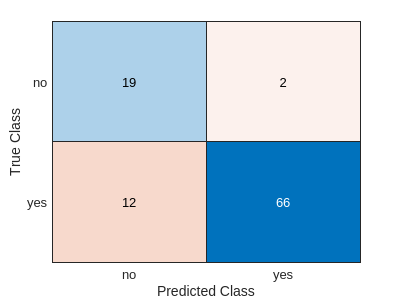


figure
confusionchart(imdsTest.Labels, preds);